# **Chapter15 mini quiz Q1 (Lec10) [ALL CORRECT]**

## **Spoiler: All of them are extremely similar!**

**Data**

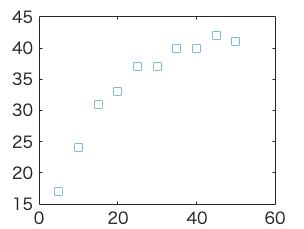

x = [5  10  15  20  25  30  35  40  45  50];
y = [17  24  31  33  37  37  40  40  42  41];
plot(x, y, 's');

**Linear fit**

poly_order_1 = polyfit(x, y, 1); % n = degree = 1

% xx = 5:2:50; % 5 to 50, steps of 2
% yy = polyval(poly_order_1, xx)
% plot(x, y, 'o', xx, yy, '-')

Sr = sum((y - polyval(poly_order_1, x)) .^ 2);
St = sum((y - mean(y)) .^ 2);

linear_r2 = 1 - (Sr/St)

linear_r2 = 0.8385

**Quadratic fit**

poly_order_2 = polyfit(x, y, 2); % n = degree = 2

% xx = 5:2:50; % 5 to 50, steps of 2
% yy = polyval(poly_order_2, xx)
% plot(x, y, 'o', xx, yy, '-')

Sr = sum((y - polyval(poly_order_2, x)) .^ 2);
St = sum((y - mean(y)) .^ 2);

quadratic_r2 = 1 - (Sr/St)

quadratic_r2 = 0.9800

**Cubic fit**

poly_order_3 = polyfit(x, y, 3); % n = degree = 3

% xx = 5:2:50; % 5 to 50, steps of 2
% yy = polyval(poly_order_3, xx)
% plot(x, y, 'o', xx, yy, '-')

Sr = sum((y - polyval(poly_order_3, x)) .^ 2);
St = sum((y - mean(y)) .^ 2);

cubic_r2 = 1 - (Sr/St)

cubic_r2 = 0.9897

**A power equation fit**

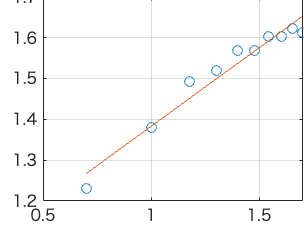

new_power_x = log10(x);
new_power_y = log10(y);

[a, ~] = linregr(new_power_x, new_power_y);


power_slope = a(1);
power_intercept = a(2);
alpha = power(10, power_intercept);
beta = power_slope;

% xp = linspace(min(x), max(x), 100)
% yp = alpha * power(xp, beta)
% plot(x, y, '*', xp, yp, '-')

y_pred_power = alpha * power(x, beta);

Sr = sum((y - y_pred_power) .^ 2);
St = sum((y - mean(y)) .^ 2);
power_r2 = 1 - (Sr/St)

power_r2 = 0.9377

**A saturation-growth-rate equation fit**

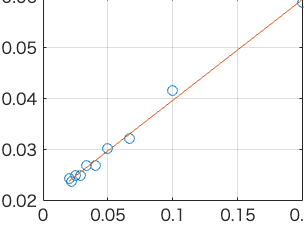

new_sat_x = 1 ./ x;
new_sat_y = 1 ./ y;

[a, r2] = linregr(new_sat_x, new_sat_y);


sat_slope = a(1);
sat_intercept = a(2);
alpha = 1 / sat_intercept;
beta = sat_slope * alpha;

% xp = linspace(min(x), max(x), 100)
% yp = alpha .* (xp ./ (beta + xp))
% plot(x, y, '*', xp, yp, '-')

y_pred_sat = alpha .* (x ./ (beta + x));

Sr = sum((y - y_pred_sat) .^ 2);
St = sum((y - mean(y)) .^ 2);
sat_r2 = 1 - (Sr/St)

sat_r2 = 0.9892